algorithm = 'RPSnet';
dataset = 'mnist';

jsd_struct = load(sprintf("%s\\%s\\inclass_jsd.mat", algorithm, dataset));
scn1_jsds = [];
scn2_jsds = [];

for i=1:length(fieldnames(jsd_struct))
    scn1_jsds = [scn1_jsds; getfield(jsd_struct, sprintf('t%d', i)).scn1];
    scn2_jsds = [scn2_jsds; getfield(jsd_struct, sprintf('t%d', i)).scn2];
end

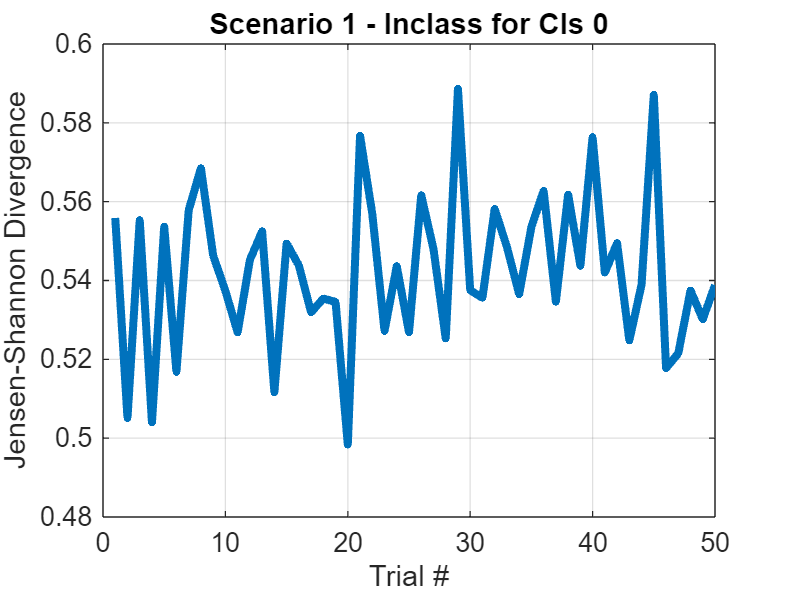

% Plot JSDs
x = 1:50;
plot(x, scn1_jsds, 'LineWidth', 3)
title('Scenario 1 - Inclass for Cls 0');
xlabel('Trial #');
ylabel('Jensen-Shannon Divergence');
grid on;

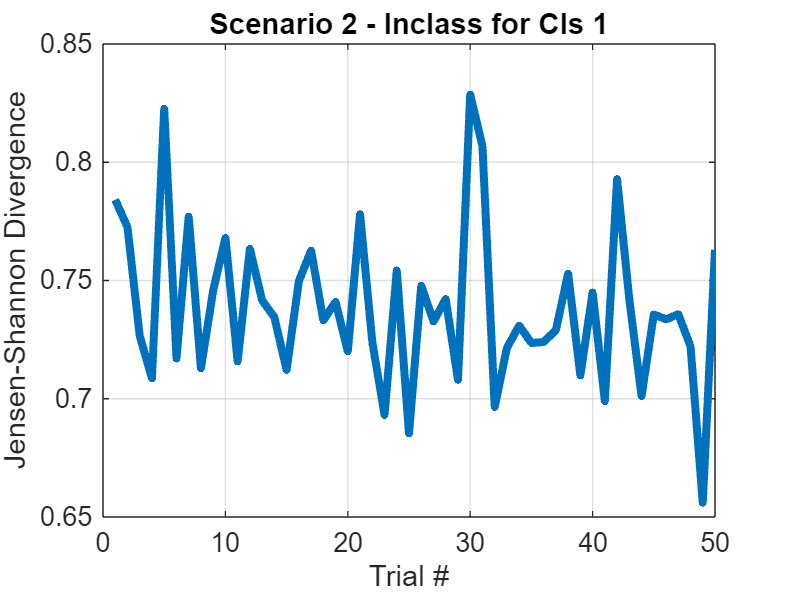


plot(x, scn2_jsds, 'LineWidth', 3)
title('Scenario 2 - Inclass for Cls 1');
xlabel('Trial #');
ylabel('Jensen-Shannon Divergence');
grid on;

% Calculate Averages and Std Dev
scn1_avg = mean(scn1_jsds)

scn1_avg = 0.5425

scn1_std = std(scn1_jsds)

scn1_std = 0.0198


scn2_avg = mean(scn2_jsds)

scn2_avg = 0.7385

scn2_std = std(scn2_jsds)

scn2_std = 0.0338


avgs = [scn1_avg; scn2_avg];
stds = [scn1_std; scn2_std];

% Create Table
scns = ["scn1", "scn2", "scn3", "scn4"];
data_table = table(avgs, stds, ...
    'VariableNames', ["Avg", "Std Dev"], 'RowNames', ["Scn 1", "Scn 2"])

data_table = 2×2 table
               Avg      Std Dev 
             _______    ________

    Scn 1    0.54245    0.019849
    Scn 2    0.73849    0.033802


% Create JSD Table
row_names = [];
for i=1:length(fieldnames(jsd_struct))
    row_names = [row_names; sprintf("Trial %d", i)];
end
scns = ["scn1", "scn2", "scn3", "scn4"];
jsd_table = table(scn1_jsds, scn2_jsds, ...
    'VariableNames', ["Scn 1", "Scn 2"], 'RowNames', row_names)

jsd_table = 50×2 table
                 Scn 1      Scn 2 
                _______    _______

    Trial 1     0.55587    0.78415
    Trial 2     0.50507    0.77252
    Trial 3     0.55533    0.72653
    Trial 4     0.50397    0.70854
    Trial 5     0.55371    0.82264
    Trial 6     0.51679    0.71693
    Trial 7     0.55782    0.77706
    Trial 8      0.5685    0.71283
    Trial 9     0.54634    0.74579
    Trial 10    0.53738    0.76803
    Trial 11    0.52682    0.71574
    Trial 12     0.5452    0.76345
    Trial 13    0.55252    0.74161
    Trial 14    0.51163    0.73443
    Trial 15     0.5494    0.71216
    Trial 16    0.54383    0.74968
